`考虑非对称的单峰光谱``，光谱设计需要考虑中心波长、半高全宽（``FWHM``）等参数，例如设定一个``FWHM``参数，修改中心波长的值。分析白光干涉信号在空域和谱域的特征，对得到的白光干涉信号测量，和理想值比较。`

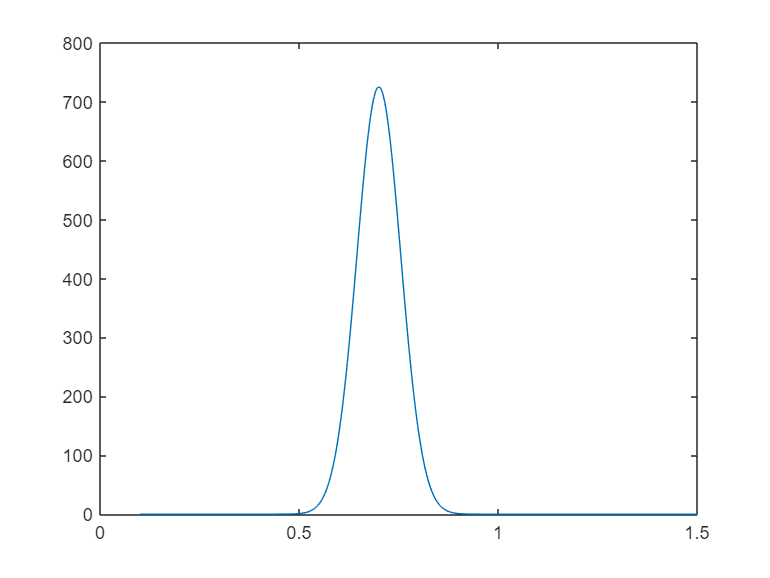

%生成非对称光谱
clc;clear all;
wl = linspace(0.1,1.5,1024);
gv1 = 100;
sigma1 = 0.055;
u1 = 0.7;
guass1 = guassf(wl,gv1,sigma1,u1);
plot(wl,guass1)

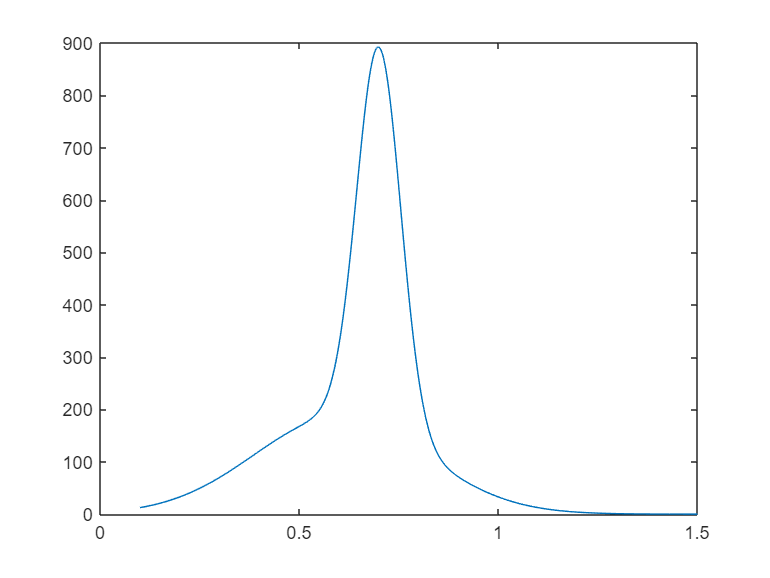

gv2 = gv1/1;
guass2 = guassf(wl,gv2,0.215,0.6); 
guass3 = guass1 + guass2;
plot(wl,guass3)

%固定光谱中心波数，改变非对称光谱的FWHM
ccwl = ccwlf(wl,guass3)

ccwl =    0.653106584391492


fwhm = fwhmf(wl,guass3)

fwhm =    0.150139923035346


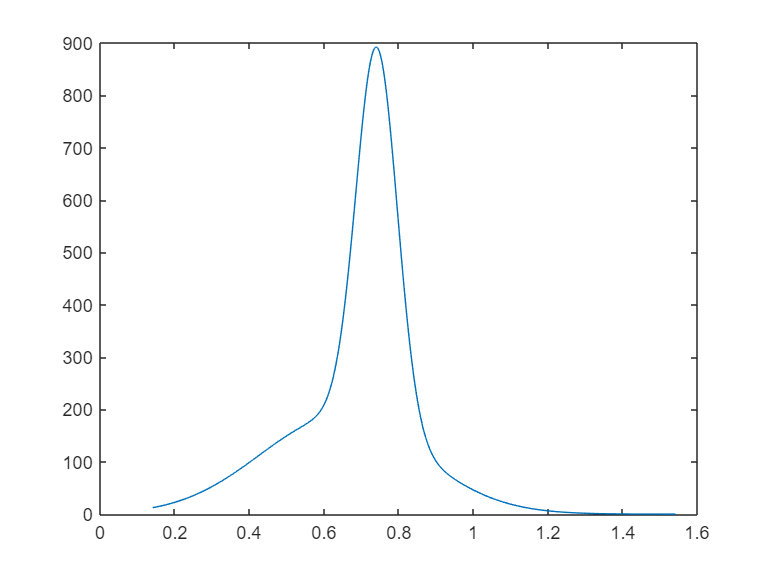

[guass3,n] = sigshift(guass3,1:numel(wl),30);
wl = 0.1+(n-1)*(wl(end)-wl(1))/(numel(wl)-1);
plot(wl,guass3);

ccwl2 = ccwlf(wl,guass3)

ccwl2 =    0.694162302866565


fwhm2 = fwhmf(wl,guass3)

fwhm2 =    0.150139923035346



spectrum_frequency = wl;
spectrum_intensity = guass3;
z0 = 20;    %单位为微米
N = 40000;
z = 10:30/40000:(N-1)*(30/40000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*(1./spectrum_frequency)));
end
disp("生成的白光干涉信号");

生成的白光干涉信号


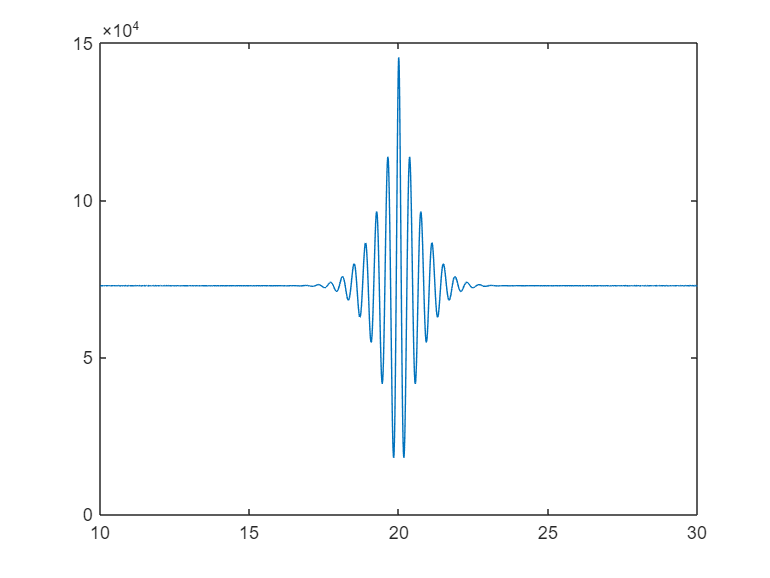

plot(z,interference_signal);

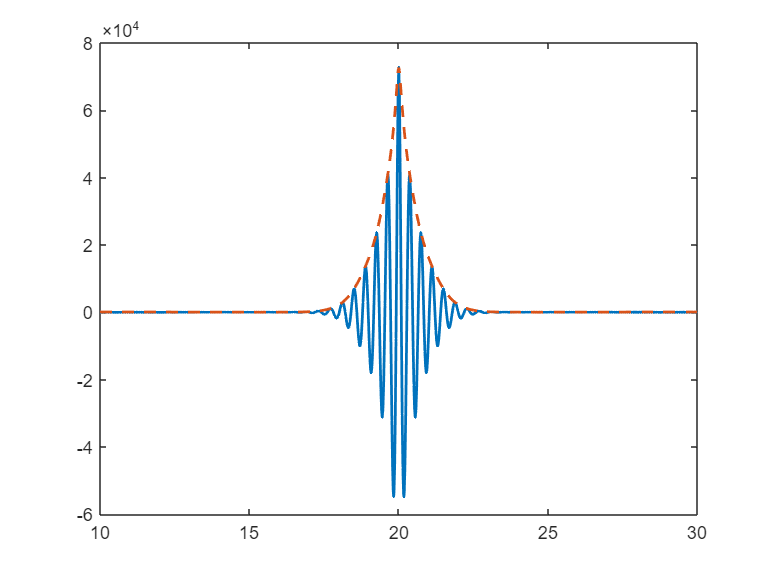

interference_signal = interference_signal-mean(interference_signal);
baoluo = hilbert(interference_signal); % Hilbert变换
baoluo = abs(baoluo);
plot(z,interference_signal,z,baoluo,'--','linewidth',1.5);

calcuV(interference_signal)

ans =    0.435645466420594


calcuW(z,interference_signal)

ans =    4.875900907890301


改变光谱的中心波长和半高宽（FWHM）.

当半高宽FWHM = 150nm时，改变光谱的中心波长.从379到926.

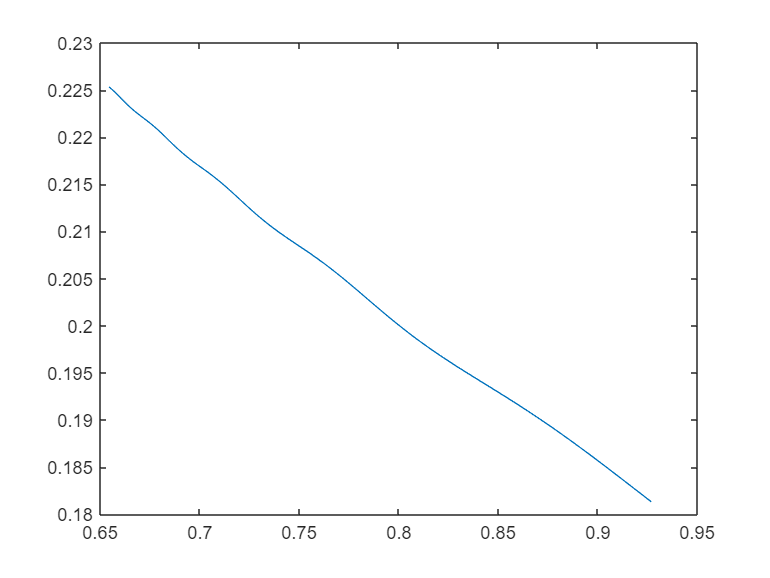

%生成白光干涉信号
%生成非对称光谱
clc;clear all;
wl = linspace(0.1,1.5,1024);
gv1 = 100;
V = zeros(1,200);
W = zeros(1,200);
ccwl1 = zeros(1,200);
sigma1 = 0.055;
u1 = 0.7;
for n1 = 1:200
wl = linspace(0.1,1.5,1024);
guass1 = guassf(wl,gv1,sigma1,u1);
gv2 = gv1/1;
guass2 = guassf(wl,gv2,0.215,0.6); 
guass3 = guass1 + guass2;
[guass3,n] = sigshift(guass3,1:numel(wl),n1);
wl = 0.1+(n-1)*(wl(end)-wl(1))/(numel(wl)-1);
spectrum_frequency = wl;
spectrum_intensity = guass3;
z0 = 20;    %单位为微米
N = 40000;
z = -10:30/40000:(N-1)*(30/40000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*(1./spectrum_frequency)));
end
%disp("生成的白光干涉信号");
% plot(z,interference_signal);
%计算零级条纹与第一级条纹的可见度和干涉条纹的空间长度
V(n1) = calcuV(interference_signal);
W(n1) = calcuW(z,interference_signal);
ccwl1(n1) = ccwlf(spectrum_frequency,guass3);
end
plot(ccwl1,V);

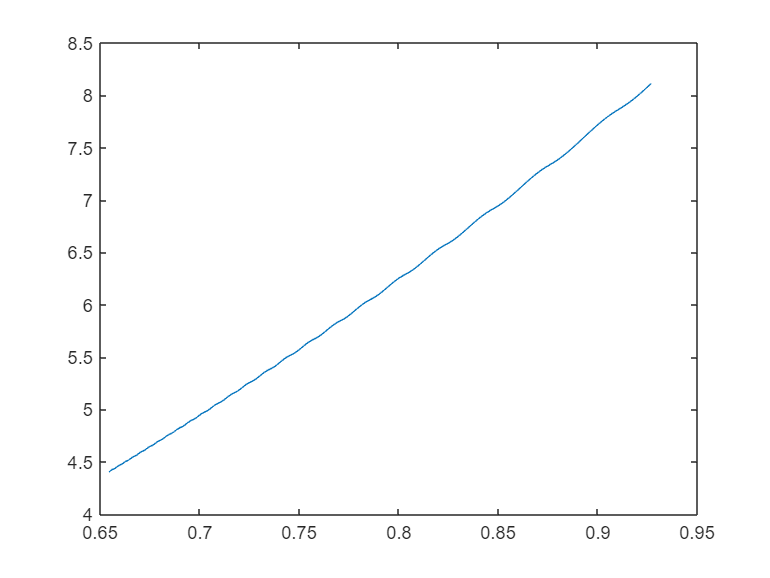

plot(ccwl1,W);

这里零级条纹与第一级条纹的可见度和干涉条纹的空间长度可以画成折线段。这里按照相同中心波长，不同半高宽（FWHM）做法照葫芦画瓢得出结论。

function guass = guassf(wl,gv,sigma,u)
guass = gv/(sigma*sqrt(2*pi))*exp(-(wl-u).^2/(2*sigma^2));
end
function fwhm = fwhmf(wl,guass)
pks = max(guass);
idx = find(diff(sign(guass-pks/2)));
fwhmn = zeros(2,1);
for i = 1:numel(idx)
    x = wl(idx(i)-2:idx(i)+2);
    y = guass(idx(i)-2:idx(i)+2);
    fwhmn(i,:) = interp1(y,x,pks/2,'pchip');
end
fwhm = diff(fwhmn);
end

function ccwl1 = ccwlf(wl,guass)
P = sum(wl.*guass);
Q = sum(guass);
ccwl1 = P/Q;
end

条纹可见度公式：V= （I0-I1）/I0

%零级条纹与第一级条纹的可见度
function V = calcuV(signal)
[pks,~] = findpeaks(signal);
pks = sort(pks,'descend');
V = (pks(1)-pks(2))/pks(1);
end

%计算干涉条纹的空间长度
function wdt = calcuW(z,signal)
signal = signal-mean(signal);
%得到信号包络
W = hilbert(signal); % Hilbert变换
W = abs(W);
% plot(z,signal,z,W,'--','linewidth',1.5)
idx = find(diff(sign(W-max(W)/100)));
    for n = 1:numel(idx)
        idxrng = idx(n)-2:idx(n)+2;
        xfwhm(1,n) = interp1(W(idxrng), z(idxrng), max(W)/100, 'pchip');
    end
    wdt = xfwhm(end)-xfwhm(1);
end

function [y,n] = sigshift(x,m,k)
%implements y(n) = x(n-k)
%----------------------------------
%[y,n]=sigshift(x,m,k)
%
n = m+k; y = x;
end